Dinámica del sistema


$$\dot{x_1}=x_2 \\
\dot{x}_2=-C_ksin(x_1) + \frac{sin(2x_1)}{4}$$


donde:


$$C_k = \frac{4g}{L\epsilon^2\omega^2$$



$$\epsilon = \frac{2\delta}{L}$$


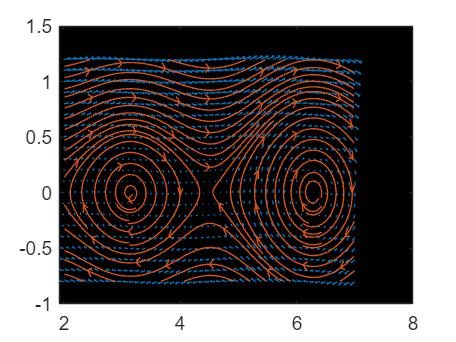

[X,Y] = meshgrid(2:0.1:7,-0.8:0.1:1.2);
%parametros de sistema:
a = 0.1;
L = 1;
w = 100;
g = 9.81;
%variables para estimar:
eps = (2*a)/L;
ck = (4*g)/(L*(eps^2)*(w^2));
%ecuaciones de la dinamica del sistema:
U = Y;
V = -ck*sin(X) - sin(2.*X)/4;
%V = (-g/L).*sin(X) - (1/2)*(((a*w)/L)^2).*sin(X).*cos(X);
%V = sin(X) .* (1/2 - 10*cos(8*1));
clear figure;

quiver(X,Y,U,V);
streamslice(X,Y,U,V);
set(gca,'Color','k')

Simulación

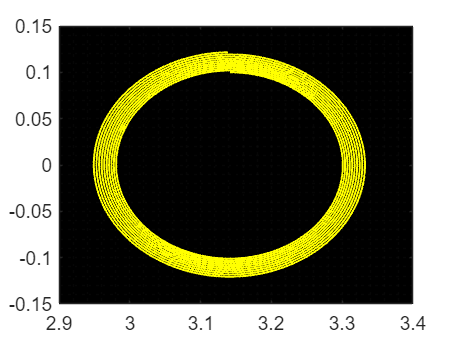

%f = @(x) [ x(2); 
%           (-g/L)*sin(x(1)) - (1/2)*(((a*w)/L)^2)*sin(x(1))*cos(x(1))];
f = @(x) [ x(2); 
           -(ck)*sin(x(1)) - sin(2*x(1))/4];

t0 = 0; % tiempo inicial
tf = 100; % tiempo (final) de simulación
dt = 0.01; % período de muestreo
K = (tf - t0) / dt; % número de iteraciones (ya que se utilizará un ciclo for)

x0 = [pi; 0.1]; % vector de condiciones iniciales
x = x0; % se inicializa el vector de estado con las condiciones iniciales

X = zeros(numel(x0), K+1); % se deja una casilla para cada iteración más una para x0 
X(:,1) = x; % se almacena de una vez x0

for k = 1:K
    x = x + f(x)*dt; % fórmula de forward Euler
    X(:, k+1) = x; % se guardan los valores del estado
end

t = linspace(t0,tf,K+1);

figure;
plot(X(1,:)', X(2,:)', 'y', 'LineWidth', 1);
set(gca,'Color','k')
grid minor;

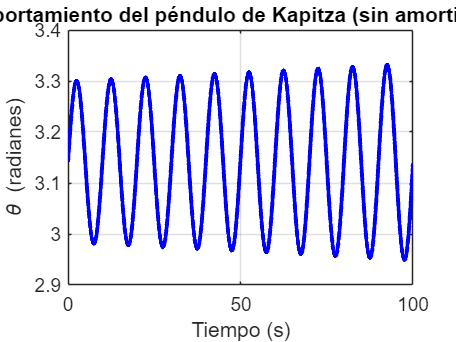


% Separar las variables de estado
theta = X(1, :);
velocidad = X(2, :);

% Gráfica del ángulo en función del tiempo
figure;
plot(t, theta, 'b', 'LineWidth', 2);
title('Comportamiento del péndulo de Kapitza (sin amortiguador)');
xlabel('Tiempo (s)');
ylabel('\theta (radianes)');
grid on;

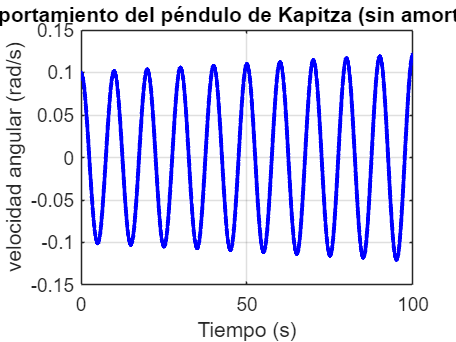


% Gráfica del ángulo en función del tiempo
figure;
plot(t, velocidad, 'b', 'LineWidth', 2);
title('Comportamiento del péndulo de Kapitza (sin amortiguador)');
xlabel('Tiempo (s)');
ylabel(['velocidad angular (rad/s)']);
grid on;